# 实验七 机翼断面下轮廓线的数值分析

## 实验目的

- 加深对各种插值算法的理解

- 熟悉使用不同类型的插值函数

- 编程实现对机翼断面下轮廓线的插值仿真和数值分析

## 实验环境

- 计算机

- MATLAB集成环境

## 实验内容与代码

### 已知某机翼断面下轮廓线上的部分数据，如表所示


$$\left\lbrack \begin{array}{cc}
\left\lbrack \begin{array}{c}
x:\\
y:
\end{array}\right\rbrack  & \left\lbrack \begin{array}{cccccccccc}
0 & 3 & 5 & 7 & 9 & 11 & 12 & 13 & 14 & 15\\
0 & 1\ldotp 2 & 1\ldotp 7 & 2\ldotp 0 & 2\ldotp 1 & 2\ldotp 0 & 1\ldotp 8 & 1\ldotp 2 & 1\ldotp 4 & 1\ldotp 6
\end{array}\right\rbrack 
\end{array}\right\rbrack$$


- 试设计出具有一定光滑度的机翼下轮廓线，并画出图形

- 以表的形式给出x每增加0.5时的y值

- 分别用拉格朗日插值，牛顿插值，三次样条插值对上述数据点进行拟合

clc;clear;
x = [0 3 5 7 9 11 12 13 14 15]

x =      0     3     5     7     9    11    12    13    14    15


y = [0 1.2 1.7 2.0 2.1 2.0 1.8 1.2 1.4 1.6]

y =          0    1.2000    1.7000    2.0000    2.1000    2.0000    1.8000    1.2000    1.4000    1.6000


xi = 0:0.5:15

xi =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000


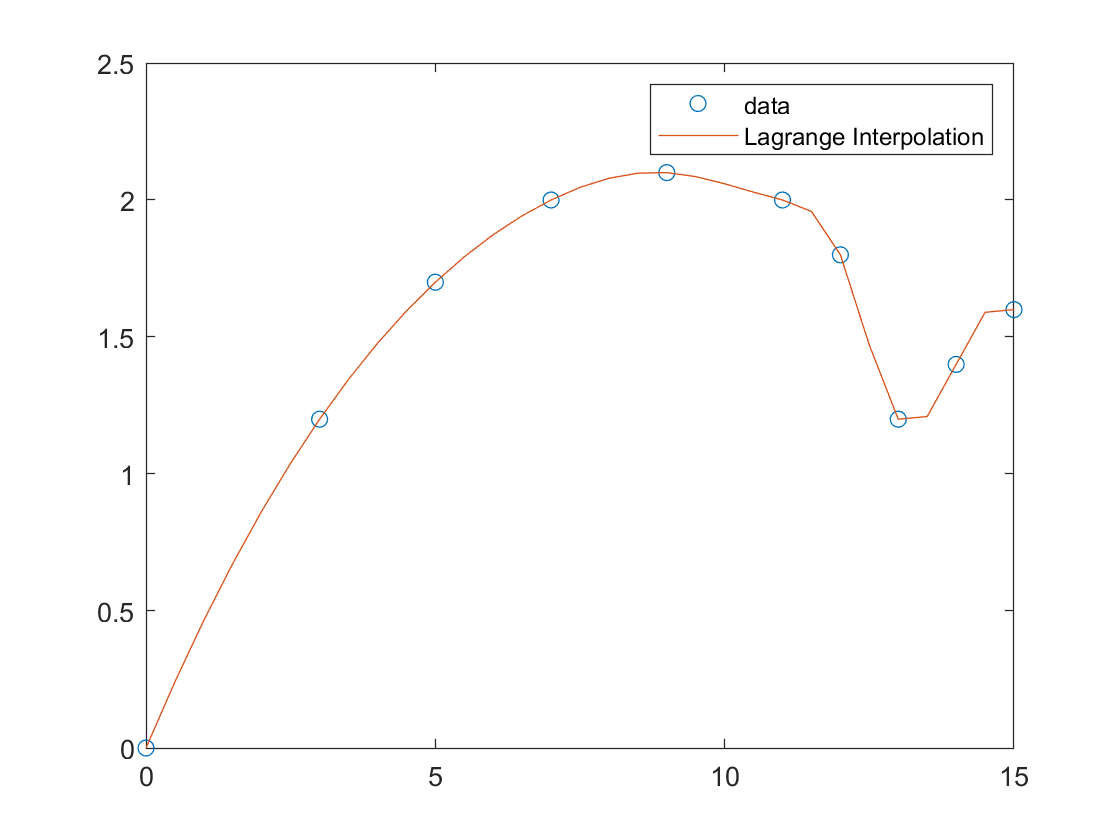

y1 = zeros(1, 31);
y2 = zeros(1, 31);

for i = 1:31
    y1(i) = lagrangeInterpolation(x, y, xi(i));
end

for i = 1:31
    y2(i) = newtonInterpolation(x, y, xi(i));
end

y3 = mySpline(x, y, xi);
plot(x, y, 'o', xi, y1, '-')
legend({'data', 'Lagrange Interpolation'})

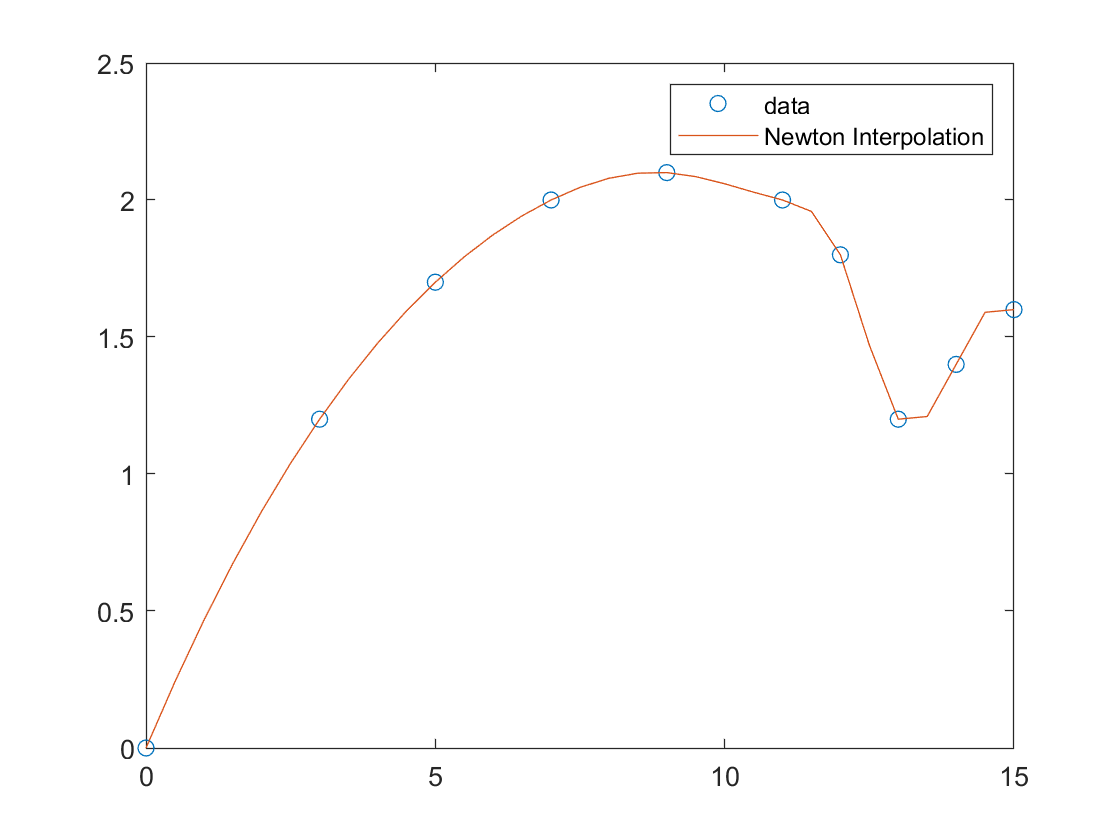

plot(x, y, 'o', xi, y2, '-')
legend({'data', 'Newton Interpolation'})

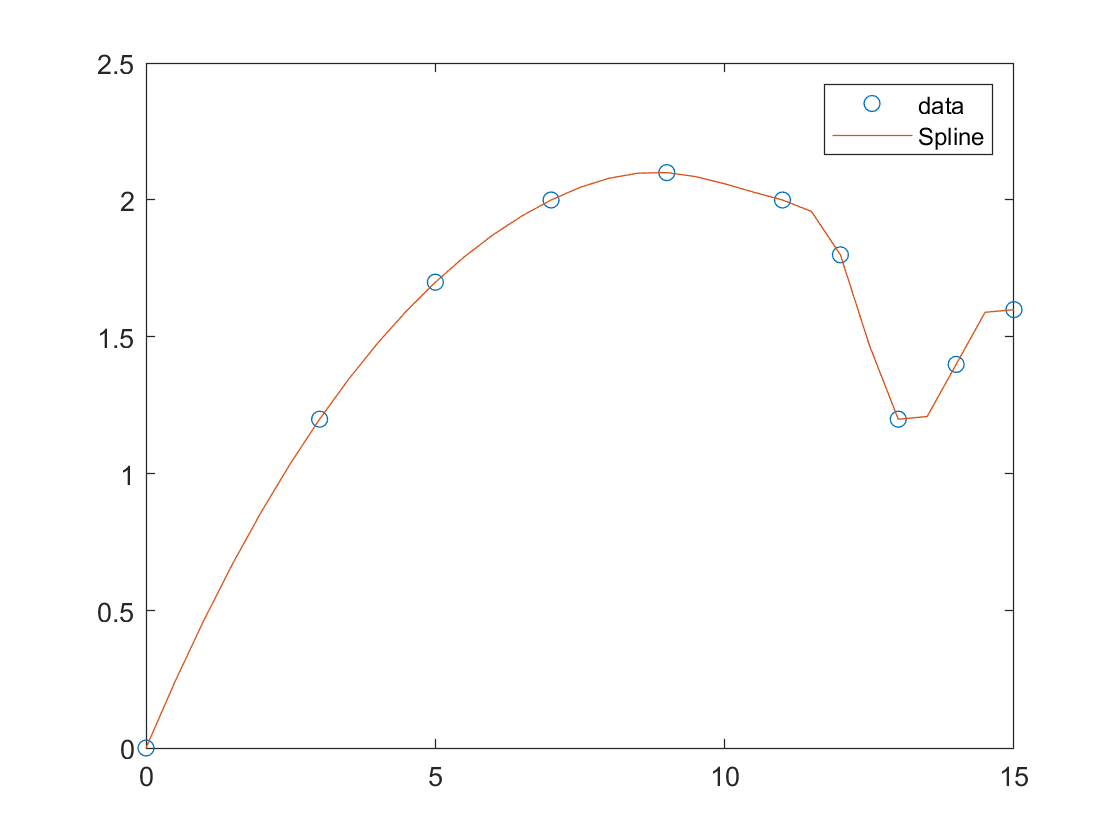

plot(x, y, 'o', xi, y3, '-')
legend({'data', 'Spline'})

### 此实时脚本中使用的函数：

%{
    Solve f(point) using the methods of Lagrange Interpolation
    
    @Title: lagrangeInterpolation
    @param x double 1d array, corresponding to the x-lable of knowing points
    in the function's plots
    @param y double 1d array, corresponding to the y-lable o knowing points
    in the function's plots
    @param point double the x-lable of the point you want to solve
    @return double 
%}

function res = lagrangeInterpolation(x, y, point)
    res = 0;
    n = length(x);
    
    for i=1:n
      xp = x([1:i-1 i+1:n]);
      res = res + y(i)*prod((point-xp)/(x(i)-xp));
    end
end

%{
    Solve f(point) using the methods of Newton Interpolation
    
    @Title: newtonInterpolation
    @param x double 1d array, corresponding to the x-lable of knowing points
    in the function's plots
    @param y double 1d array, corresponding to the y-lable o knowing points
    in the function's plots
    @param point double the x-lable of the point you want to solve
    @return double 
%}
function res = newtonInterpolation(x, y, point)
    n = length(x);
    f = zeros(n,n);
     
    % Assign values to the first column of the difference quotient table
    for k = 1:n      
        f(k) = y(k);
    end
    % Solve the difference quotient table
    for i = 2:n       % The difference quotient table starts from order 0; but the matrix is stored from dimension 1
        for k = i:n
            f(k,i) = (f(k,i-1)-f(k-1,i-1))/(x(k)-x(k+1-i));  
        end
    end
     
    % Solve the Newton Interpolation Formular
    p=0;
    
    for k=2:n
        t=1;
        for j=1:k-1
            t=t*(point-x(j));
        end
        p=f(k,k)*t+p;
    end
    p = f(1,1) + p;
    
    res = p;
end

function output = mySpline(x,y,xq)
    %SPLINE Cubic spline data interpolation.
    %   YQ = MYSPLINE(X,Y,XQ) performs cubic spline interpolation using the
    %   values Y at sample points X to find interpolated values YQ at the query
    %   points XQ.
    %       - X must be a vector.
    %       - If Y is a vector, Y(j) is the value at X(j).
    %       - If Y is a matrix or n-D array, Y(:,...,:,j) is the value at X(j).
    %
    %   SPLINE chooses slopes at X(j) such that YQ has a continuous second
    %   derivative. Thus, SPLINE produces smooth results.
    %
    %   Ordinarily, SPLINE uses not-a-knot conditions for the end slopes at
    %   X(1) and X(end). However, if Y contains two more values than X has
    %   entries, then the first and last value in Y are used as the end slopes.
    %
    %   PP = SPLINE(X,Y) returns the piecewise polynomial form PP of the
    %   interpolant. You can use PP as an input to PPVAL or UNMKPP.
    %
    %   Example: Interpolate a sine-like curve over a finer mesh
    %
    %       x = 0:10;
    %       y = sin(x);
    %       xq = 0:.25:10;
    %       yq = mySpline(x,y,xq);
    %       figure
    %       plot(x,y,'o',xq,yq)
    %
    %   Example: Perform spline interpolation with prescribed end slopes.
    %            Set the slopes to zero at the end points of the interpolant.
    %
    %       x = -4:4;
    %       y = [0 .15 1.12 2.36 2.36 1.46 .49 .06 0];
    %       cs = mySpline(x,[0 y 0]);
    %       xq = linspace(-4,4,101);
    %       figure
    %       plot(x,y,'o',xq,ppval(cs,xq));
    
    % Check and adjust input data
    [x,y,sizey,endslopes] = chckxywp(x,y);
    n = length(x);
    yd = prod(sizey);
    
    % Generate the cubic spline interpolant in ppform
    dd = ones(yd,1);
    dx = diff(x);
    divdif = diff(y,[],2)./dx(dd,:);
    if n == 2
        if isempty(endslopes)
            % the interpolant is a straight line
            pp = mkpp(x,[divdif y(:,1)],sizey);
        else
            % the interpolant is the cubic Hermite polynomial
            pp = pwch(x,y,endslopes,dx,divdif);
            pp.dim = sizey;
        end
    elseif n == 3 && isempty(endslopes)
        % the interpolant is a parabola
        y(:,2:3) = divdif;
        y(:,3) = diff(divdif')'/(x(3)-x(1));
        y(:,2) = y(:,2)-y(:,3)*dx(1);
        pp = mkpp(x([1,3]),y(:,[3 2 1]),sizey);
    else
        % set up the sparse, tridiagonal, linear system b = ?*c for the slopes
        b = zeros(yd,n);
        b(:,2:n-1) = 3*(dx(dd,2:n-1).*divdif(:,1:n-2)+dx(dd,1:n-2).*divdif(:,2:n-1));
        if isempty(endslopes)
            x31 = x(3)-x(1);
            xn = x(n)-x(n-2);
            b(:,1) = ((dx(1)+2*x31)*dx(2)*divdif(:,1)+dx(1)^2*divdif(:,2))/x31;
            b(:,n) = (dx(n-1)^2*divdif(:,n-2)+(2*xn+dx(n-1))*dx(n-2)*divdif(:,n-1))/xn;
        else
            x31 = 0;
            xn = 0;
            b(:,[1 n]) = dx(dd,[2 n-2]).*endslopes;
        end
        dxt = dx(:);
        c = spdiags([ [x31;dxt(1:n-2);0] ...
            [dxt(2);2*(dxt(2:n-1)+dxt(1:n-2));dxt(n-2)] ...
            [0;dxt(2:n-1);xn] ],[-1 0 1],n,n);
        
        % sparse linear equation solution for the slopes
        mmdflag = spparms('autommd');
        spparms('autommd',0);
        s = b/c;
        spparms('autommd',mmdflag);
        
        % construct piecewise cubic Hermite interpolant
        % to values and computed slopes
        pp = pwch(x,y,s,dx,divdif);
        pp.dim = sizey;
    end
    
    if nargin == 2
        output = pp;
    else
        output = ppval(pp,xq);
    end
end